%% Calculate the joint density of two normal distributions:
xlim = -2:0.1:4;
ylim = -3:0.1:3;

[X,Y] = meshgrid(xlim, ylim);
distr = zeros(size(X));

for i = 1:size(X,1)
    
    for j = 1:size(X,2)
        
        distr(i,j) = copulapdf("Gaussian", [normcdf(X(i,j),1, 1), normcdf(Y(i,j),0,1)], [1,0.4; 0.4, 1]).*normpdf(X(i,j),0,1).*normpdf(Y(i,j),1,1);
        
    end
end


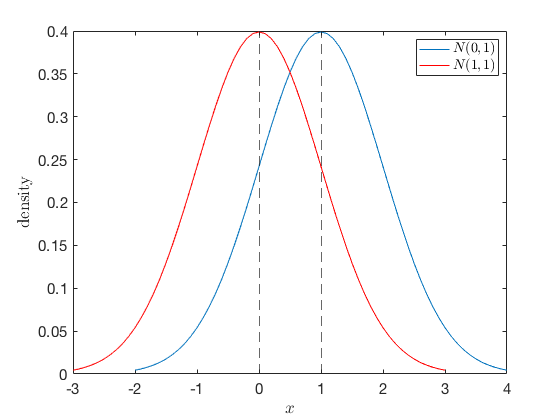


fig = figure;
% subplot(1,2,2);
plot(xlim, normpdf(xlim, 1,1));
hold on;
plot(ylim, normpdf(ylim, 0,1), 'Color','red');
ylabel(["density"], 'Interpreter', 'latex');
xlabel("$x$", 'Interpreter',"latex");
xline(0, 'LineStyle', '--');
xline(1, 'LineStyle', '--');
legend(["$N(0,1)$", "$N(1,1)$"], 'Interpreter',"latex");
saveas(fig, "/Users/Florian-Kuhm/Desktop/WLoss2Densities.epsc")
ax = gca();
ax.FontSize = 15;


% subplot(1,2,2);
% surface(X,Y,distr);
% hold on;
% plot3(xlim,(ylim(1)).*ones(size(xlim)), normpdf(xlim, 1,1));
% plot3(zeros(size(ylim)), ylim, normpdf(ylim, 0,1), 'Color','red');
% box on;



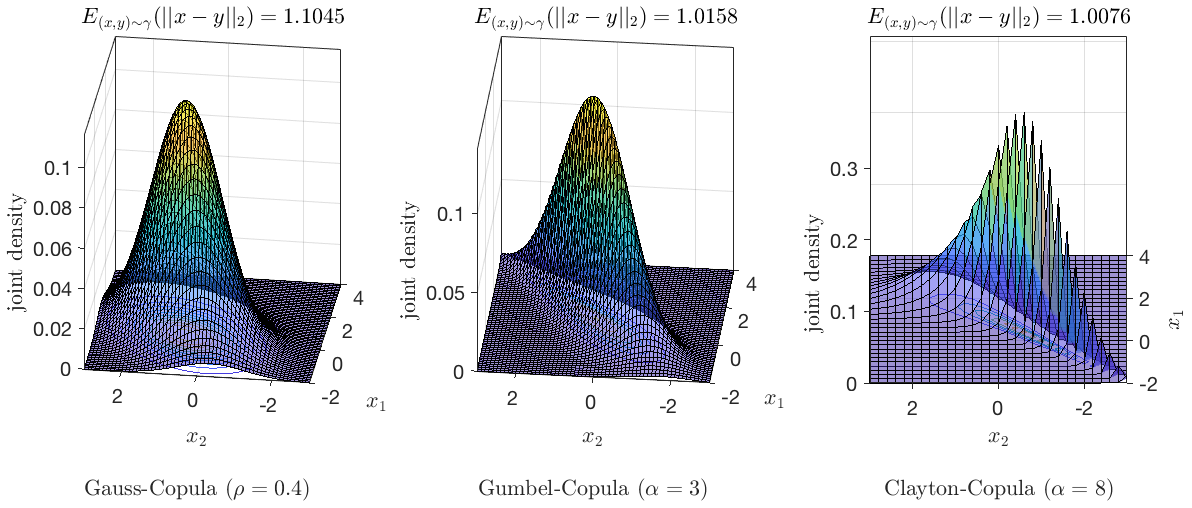

fig = figure;
tiledlayout(1,3,'TileSpacing',"compact",'Padding',"compact");
fig.Position = [-283, 154, 1192, 508];

nexttile;
surfc(X,Y,distr, 'FaceAlpha', 0.5);
box on;
title("$E_{(x,y)\sim \gamma}(||x-y||_2) = " + ...
    round(integral2(@(x,y)(abs(x-y).*reshape(mvnpdf([x(:),y(:)], [0,1], [1,0.4; 0.4, 1]), size(x))), xlim(1), xlim(end), ylim(1), ylim(end)),4) + "$", ...
    "Interpreter","latex");
ylabel(["$x_2$";"";"Gauss-Copula $(\rho = 0.4)$"], 'Interpreter', 'latex');
xlabel("$x_1$", 'Interpreter',"latex");
zlabel("joint density", 'Interpreter',"latex");
ax = gca();
ax.FontSize = 20;
view([-82, 23]);

% Gumbel-Copula instead:
xlim = -2:0.1:4;
ylim = -3:0.1:3;

[X,Y] = meshgrid(xlim, ylim);
distr = zeros(size(X));

for i = 1:size(X,1)
    
    for j = 1:size(X,2)
        
        distr(i,j) = copulapdf("Gumbel", [normcdf(X(i,j),1, 1), normcdf(Y(i,j),0,1)], 3).*normpdf(X(i,j),0,1).*normpdf(Y(i,j),1,1);
        
    end
end


nexttile;
surfc(X,Y,distr, 'FaceAlpha', 0.5);
box on;

dens = @(x,y)(copulapdf("Gumbel", [normcdf(x(:),1, 1), normcdf(y(:),0,1)], 3).*normpdf(x(:),1,1).*normpdf(y(:),0,1));
title("$E_{(x,y)\sim \gamma}(||x-y||_2) = " + ...
    round(integral2(@(x,y)(abs(x-y).*reshape(dens(x,y), size(x))), xlim(1), xlim(end), ylim(1), ylim(end)),4) + "$", ...
    "Interpreter","latex");
    
ylabel(["$x_2$";"";"Gumbel-Copula $(\alpha = 3)$"], 'Interpreter', 'latex');
xlabel("$x_1$", 'Interpreter',"latex");
zlabel("joint density", 'Interpreter',"latex");
ax = gca();
ax.FontSize = 20;
view([-84, 27]);




% Clayton-Copula instead:
xlim = -2:0.2:4;
ylim = -3:0.2:3;

[X,Y] = meshgrid(xlim, ylim);
distr = zeros(size(X));

for i = 1:size(X,1)
    
    for j = 1:size(X,2)
        
        distr(i,j) = copulapdf("Clayton", [normcdf(X(i,j),1, 1), normcdf(Y(i,j),0,1)], 8).*normpdf(X(i,j),0,1).*normpdf(Y(i,j),1,1);
        
    end
end


nexttile;
surfc(X,Y,distr, 'FaceAlpha', 0.5);
box on;

dens = @(x,y)(copulapdf("Clayton", [normcdf(x(:),1, 1), normcdf(y(:),0,1)], 8).*normpdf(x(:),1,1).*normpdf(y(:),0,1));
title("$E_{(x,y)\sim \gamma}(||x-y||_2) = " + ...
    round(integral2(@(x,y)(sqrt((x-y).^2).*reshape(dens(x,y), size(x))), xlim(1), xlim(end), ylim(1), ylim(end)),4) + "$", ...
    "Interpreter","latex");
ylabel(["$x_2$";"";"Clayton-Copula $(\alpha = 8)$"], 'Interpreter', 'latex');
xlabel("$x_1$", 'Interpreter',"latex");
zlabel("joint density", 'Interpreter',"latex");
ax = gca();
ax.FontSize = 20;
view([-90,30]);

saveas(fig, "/Users/Florian-Kuhm/Desktop/WLossCopula.epsc")